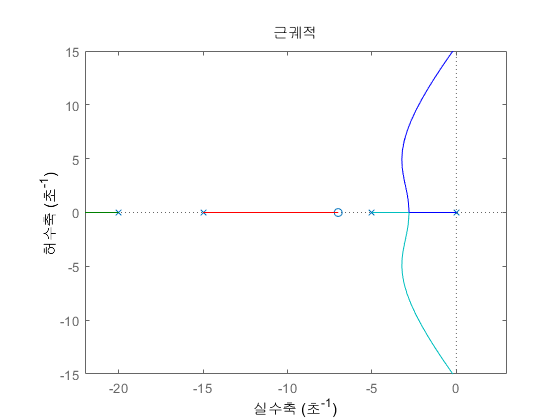

num = [1, 7];
% 두 n차 방정식의 곱을 구할 수 있다.
den = conv(conv([1, 0], [1, 5]), conv([1, 15], [1, 20]));
% root locus를 그려준다.
rlocus(num, den)
axis([-22, 3, -15, 15])

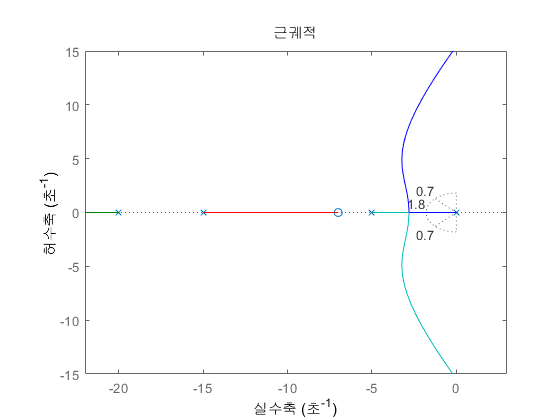

zeta = 0.7;
Wn = 1.8;
% Wn이 같을 때의 궤적, zeta가 같을 때의 궤적을 그려준다.
sgrid(zeta, Wn)

Select a point in the graphics window


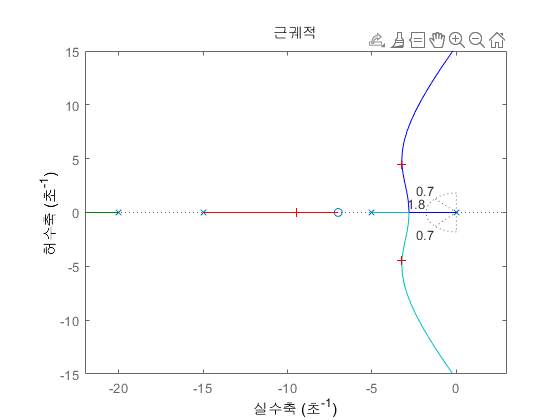

selected_point = -3.7239 + 4.4582i

kd = 996.2971

poles =  -24.0794 + 0.0000i
  -9.4748 + 0.0000i
  -3.2229 + 4.4923i
  -3.2229 - 4.4923i


% 마우스를 클릭한 곳에 해가 있기 위한 k값과 pole 값을 알려준다.
[kd, poles] = rlocfind(num,den)

%단위 피드백을 구해준다.
[numCL, denCL] = cloop(kd*num, den)

numCL = 	1.0e+03 *

         0         0         0    0.9963    6.9741


denCL = 	1.0e+03 *

    0.0010    0.0400    0.4750    2.4963    6.9741


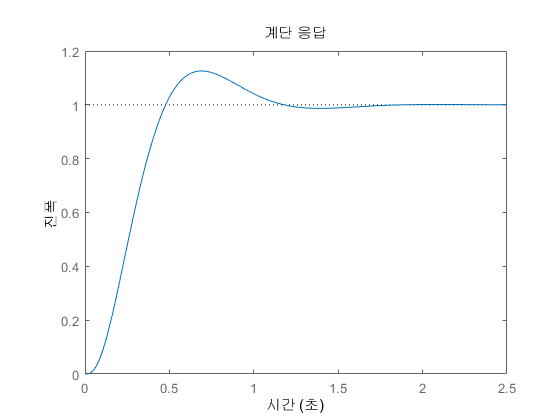

step(numCL, denCL)